# Teoria delle strutture - PROBLEMA 6

% Arco di forma parabolica schematizzato come una trave flessibile (e inestensibile)
% ad asse curvilineo
% di rigidezza flessionale EJ.

## Clear workspace and close any open windows

clear all
close all

## SOLUZIONE PUNTO 1 

% 1) Mostrare che le sollecitazioni nell’arco, nel caso in cui sia soggetto esclusivamente al
% carico distribuito d’intensità uniforme p, mostrato nella figura a sinistra, si riducono al solo
% sforzo normale, variabile lungo la linea d’asse. Determinare l’andamento dello sforzo
% normale.


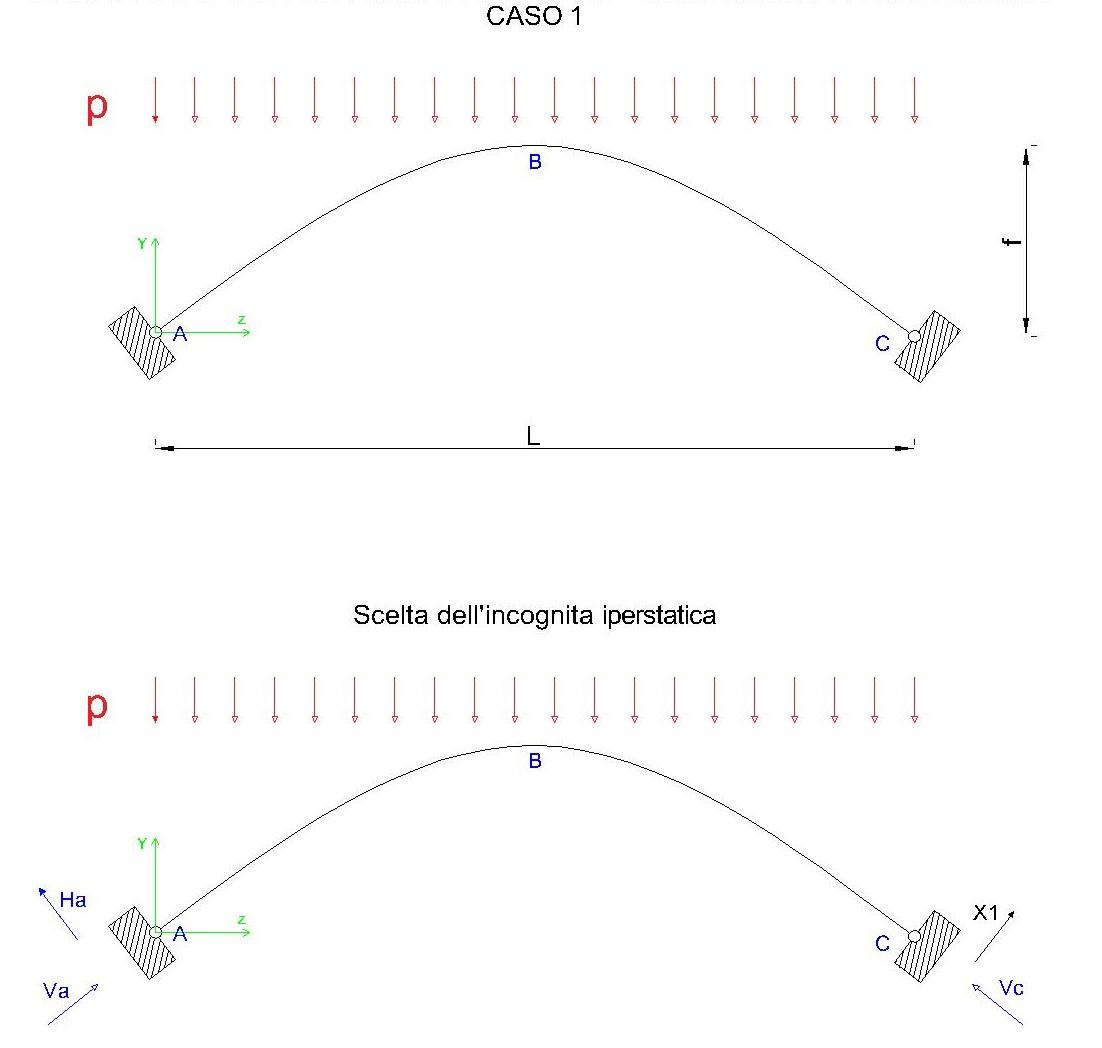

## SIMBOLICO

syms f L a b c z real
assume(f>0 & L>0)

## Determino l'equazione della nostra parabola

F(z)=a*z^2+b*z+c % Equazione della parabola 

$$F(z) = a\,z^{2}+b\,z+c$$

% SISTEMA D'EQUAZIONI PER TROVARE LA FUNZIONE DELLA PARABOLA DATA 
delta=b^2-4*a*c;
% fisso che la cordinata x del vertice della parabloa passi per un determinato punto
E1=-b/(2*a)==L/2; 
% fisso che la cordinata y del vertice della parabloa passi per un determinato punto
E2=-delta/(4*a)==f;
% fisso che la èarabola passi per punto A ''il nostro vincolo'' 
E3=F(0)==0; 
% Risolvo il sistema
S=solve([E1 E2 E3],[a b c]);
a_1=S.a(1)

$$a\_1 = -\frac{4\,f}{L^{2}}$$

b_1=S.b(1)

$$b\_1 = \frac{4\,f}{L}$$

c_1=S.c(1)

$$c\_1 = 0$$

% L'equazione della parabola diventa:
G(z)=simplify(subs(F,[a b c],[a_1 b_1 c_1]))

$$G(z) = \frac{4\,f\,z\,\left(L-z\right)}{L^{2}}$$

## Derivate della funzione parabolica

D1=simplify(diff(G,z)) % Derivata prima 

$$D1(z) = \frac{4\,f\,\left(L-2\,z\right)}{L^{2}}$$

D2=simplify(diff(D1,z)) % Derivata seconda 

$$D2(z) = -\frac{8\,f}{L^{2}}$$

## PARAMETRIZZAZIONE DELLA CURVA

tan=D1              % porto tang_θ in funzione di z

$$tan(z) = \frac{4\,f\,\left(L-2\,z\right)}{L^{2}}$$

ds=simplify(sqrt(1+D1^2)) % porto ds in funzione di z 

$$ds(z) = \sqrt{\frac{16\,f^{2}\,{\left(L-2\,z\right)}^{2}}{L^{4}}+1}$$

SIN(z)=D1/ds        % porto sin_θ in funzione di z 

$$SIN(z) = \frac{4\,f\,\left(L-2\,z\right)}{L^{2}\,\sqrt{\frac{16\,f^{2}\,{\left(L-2\,z\right)}^{2}}{L^{4}}+1}}$$

COS(z)=1/ds         % porto cos_θ in funzione di z

$$COS(z) = \frac{1}{\sqrt{\frac{16\,f^{2}\,{\left(L-2\,z\right)}^{2}}{L^{4}}+1}}$$

## SISTEMA FO

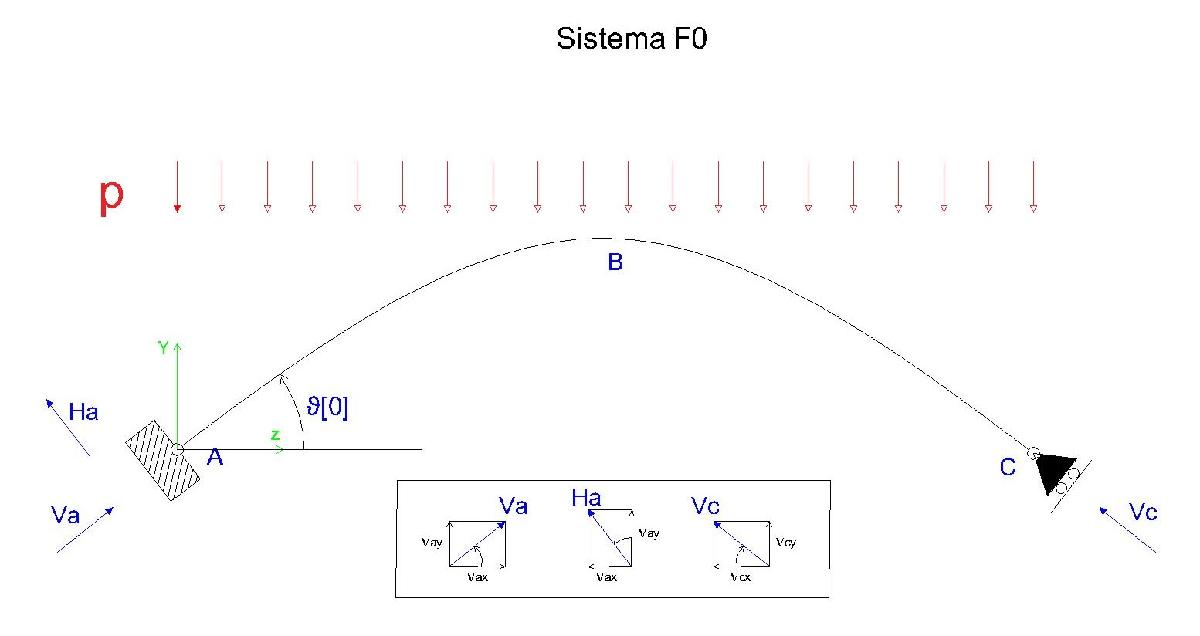

syms VA VC HA p real
% equazione alla traslazione orizzontale 
E4=(VA-VC)*COS(0)-HA*SIN(0)==0

$$E4 = \frac{\mathrm{VA}-\mathrm{VC}}{\sqrt{\frac{16\,f^{2}}{L^{2}}+1}}-\frac{4\,\mathrm{HA}\,f}{L\,\sqrt{\frac{16\,f^{2}}{L^{2}}+1}}=0$$

% equazione alla traslazione verticale 
E5=L*p-HA*COS(0)-(VA +VC)*SIN(0)==0 

$$E5 = L\,p-\frac{\mathrm{HA}}{\sqrt{\frac{16\,f^{2}}{L^{2}}+1}}-\frac{4\,f\,\left(\mathrm{VA}+\mathrm{VC}\right)}{L\,\sqrt{\frac{16\,f^{2}}{L^{2}}+1}}=0$$

% equazione alla rotazione in A 
E6=L*VC*SIN(0)-(L^2)*p/2==0;
% Risolvo il sistema
SO=solve([E4 E5 E6],[VA VC HA]);
HA0=SO.HA(1)

$$HA0 = 0$$

VA0=SO.VA(1)

$$VA0 = \frac{L^{2}\,p\,\sqrt{\frac{16\,f^{2}}{L^{2}}+1}}{8\,f}$$

VC0=SO.VC(1)

$$VC0 = \frac{L^{2}\,p\,\sqrt{\frac{16\,f^{2}}{L^{2}}+1}}{8\,f}$$

## Momento in F0

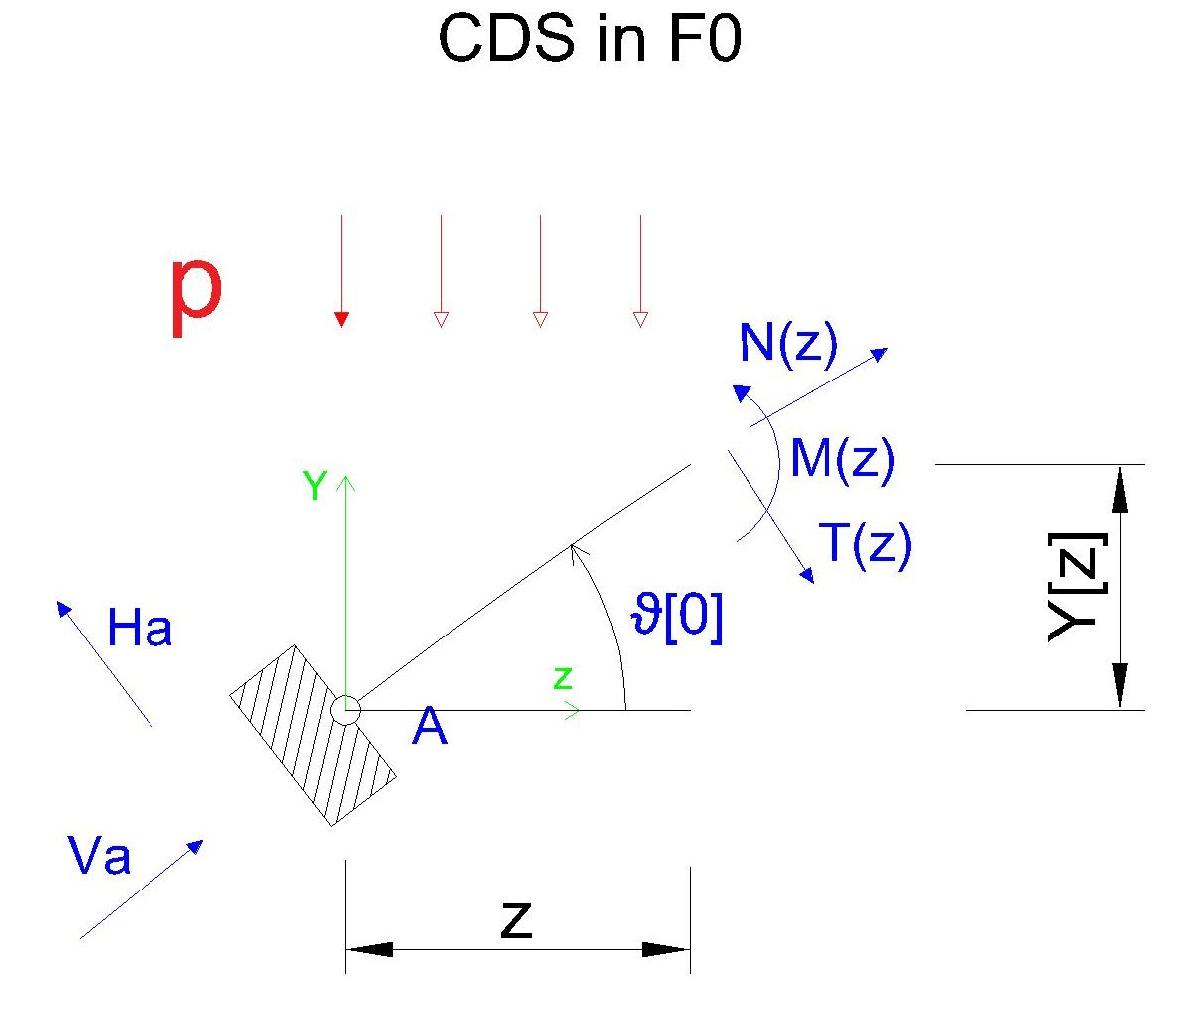

% Momento
M0(z)=simplify(-((p*z^2)/2)+VA0*SIN(0)*(z)-VA0*COS(0)*G(z))

$$M0(z) = 0$$

% (poichè il momento è nullo , anche il taglio sarà nullo essendo T=M')
% mi riduco al caso di solo N(z)

## SISTEMA F1

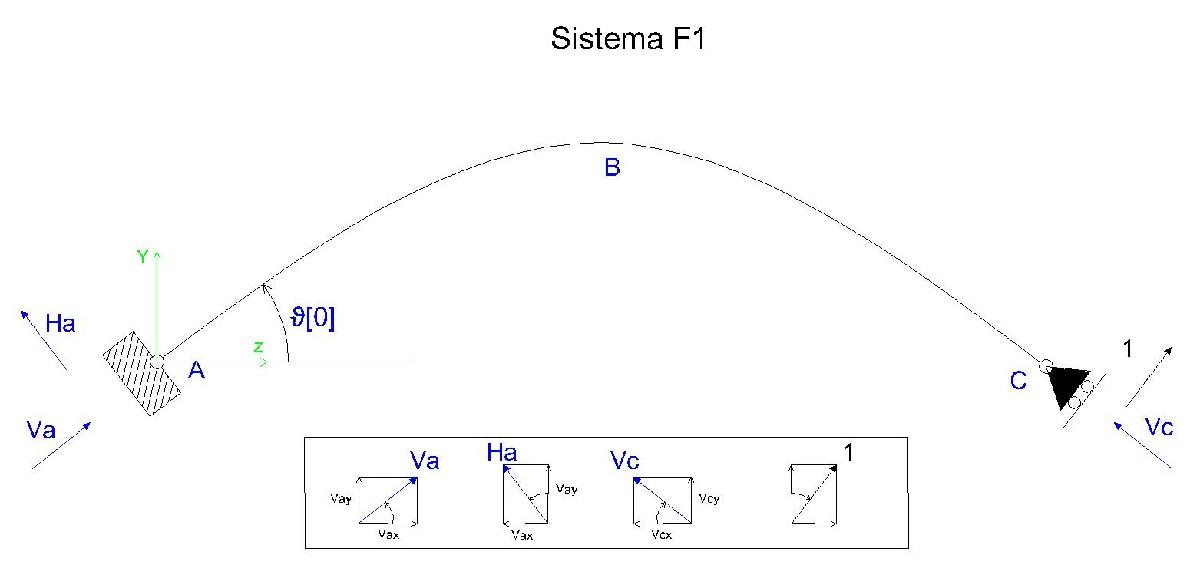

% equazione alla traslazione orizzontale 
E7=VA*COS(0)-HA*SIN(0)-VC*COS(0)+1*SIN(0)==0;
% equazione alla traslazione verticale 
E8=-VA*SIN(0)-VC*SIN(0)-HA*COS(0)-1*COS(0)==0;
% equazione alla rotazione in A 
E9=VC*SIN(0)*L+1*COS(0)*L==0;
% Risolvo il sistema
S1=solve([E7 E8 E9],[VA VC HA]);
HA1=S1.HA(1)

$$HA1 = 1$$

VA1=S1.VA(1)

$$VA1 = -\frac{L}{4\,f}$$

VC1=S1.VC(1)

$$VC1 = -\frac{L}{4\,f}$$

## Momento in F1

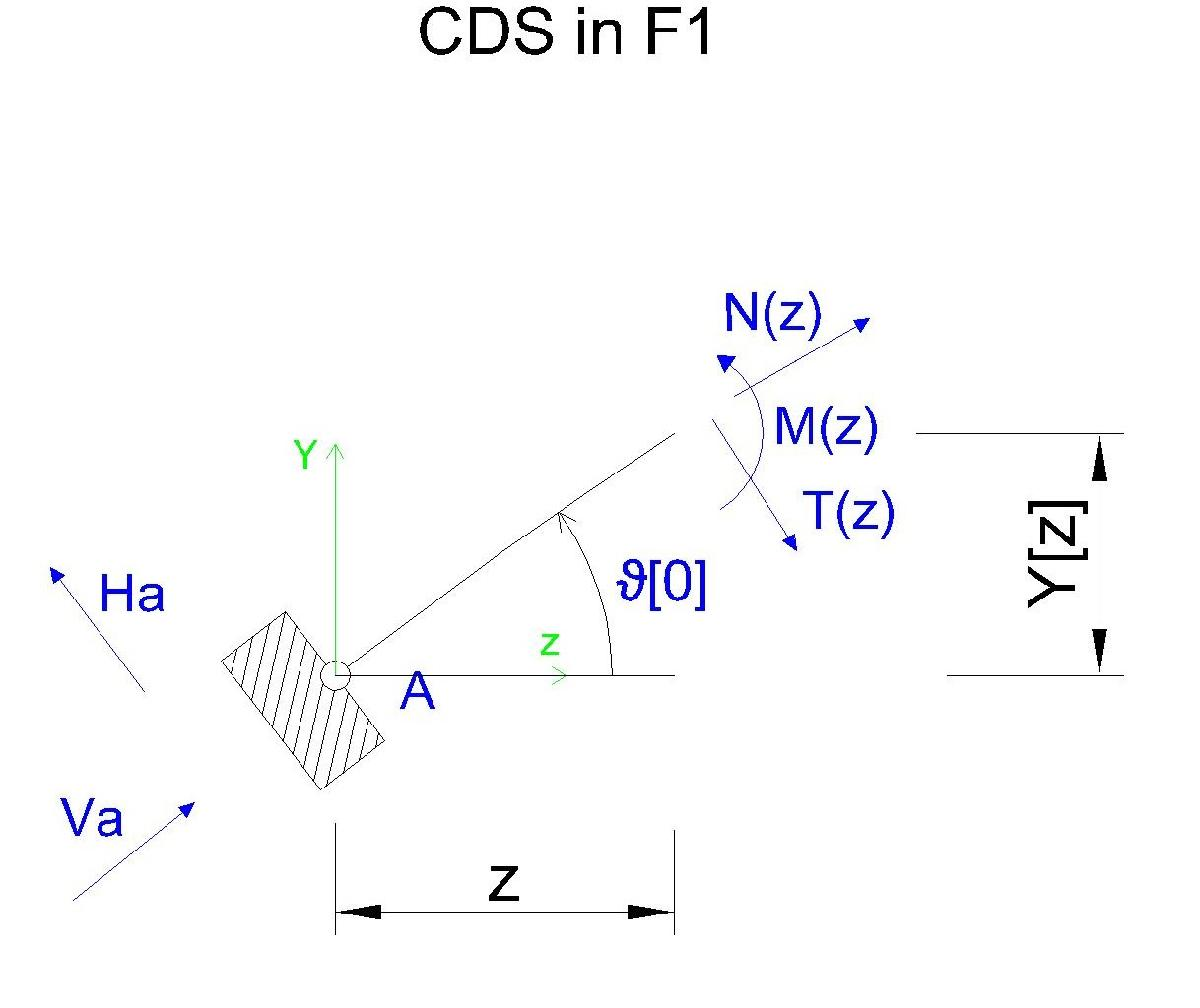

% Momento in F1 
M1(z)=simplify(VA1*SIN(0)*z-VA1*COS(0)*G(z)+1*COS(0)*(z)+1*SIN(0)*G(z))

$$M1(z) = \frac{z\,\sqrt{L^{2}+16\,f^{2}}\,\left(L-z\right)}{L^{2}}$$

## MULLER-BRESLAU

syms E J real
assume(E>0 & J>0)
Lv10=simplify(int(M1(z)*M0(z)/(E*J)*ds,z,0,L))

$$Lv10 = 0$$

Lv11=1; %Lv11 =int(M1(z)^2/(E*J)*ds,z,0,L); 
% Lv11 è difficile da calcolare, 
% per diminuire l'onere computazionale di matlab
% non faccio vedere il risultato
n10 =Lv10 ; n11 =Lv11;
% n1=n10+X1*n11==0;
X1=(-n10/n11)

$$X1 = 0$$

## CALCOLO DELLE REAZIONI VINCOLARI 

VAE=VA0+X1*VA1 % VA esatto

$$VAE = \frac{L^{2}\,p\,\sqrt{\frac{16\,f^{2}}{L^{2}}+1}}{8\,f}$$

HAE=HA0+X1*HA1 % HA esatto 

$$HAE = 0$$

## CALCOLO DELLE CDS ESATTE

M1E=M0(z)+X1*M1(z) % Momento esatto

$$M1E = 0$$

N1E=simplify(-VAE*(COS(0))/COS(z)) % Forza normale esatta

$$N1E = -\frac{L^{2}\,p\,\sqrt{\frac{16\,f^{2}\,{\left(L-2\,z\right)}^{2}}{L^{4}}+1}}{8\,f}$$

## PLot Punto 1

% Per disegnare i diagrammi devo passare a definire
% qualche variabile
% faccio 3 casi
%% CASO f=L/2
Ln=17; 
fn=Ln/2;
pn=11,25;

pn =          11.00


Y(z)=subs(G,[f L],[fn Ln]);
Nn(z)=subs(N1E,[f L p],[fn Ln pn])

$$Nn(z) = -\frac{187\,\sqrt{\frac{4\,{\left(2\,z-17\right)}^{2}}{289}+1}}{4}$$

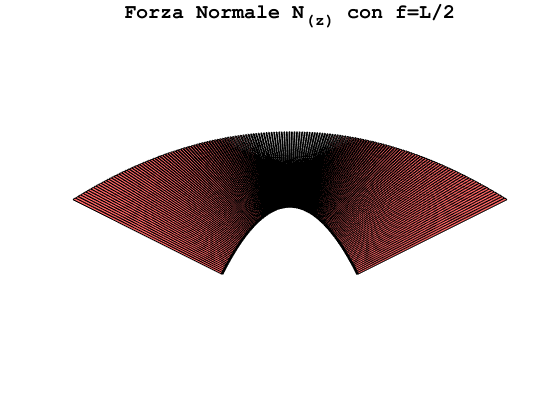

a=0:0.1:Ln;       
ang(z)=atan(subs(D1,[f L],[fn Ln]));
angle=ang(a);
N0n=double(Nn(a));
figure(1)
c=1/5;
fig = gcf; % current figure handle
fig.Color = [1 1 1];
fig.ToolBar = 'none';
for n=1:length(a)-1 
 B=double([a(n) a(n+1)  (a(n+1)+c*N0n(n+1)*sin(angle(n+1)))  (a(n)+c*N0n(n)*sin(angle(n+1)))]);
 C=double([Y(a(n)) Y(a(n+1))  (Y(a(n+1))-c*N0n(n+1)*cos(angle(n+1)))  (Y(a(n))-c*N0n(n)*cos(angle(n)))]);
hpatch=patch(B,C,'r','Facealpha',0.6);
axis equal
axis off
hold on  
end
%Struttura
plot(a,Y(a),'-k','LineWidth',2)
title(['\fontname{Courier}\fontsize{15}Forza Normale N_(_z_) con f=L/2'],'color','K');
axis equal
axis off
hold on

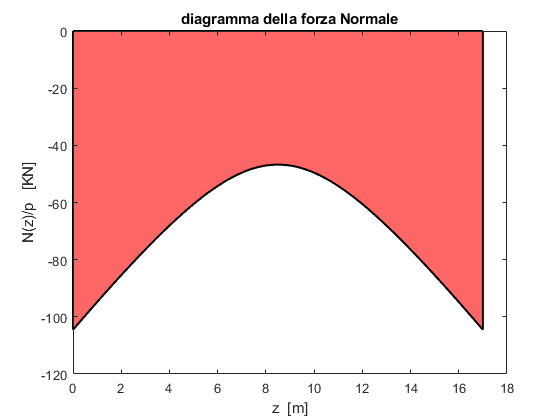

% plot per i valori
figure(2)
area(a,N0n,'FaceColor', 'r','LineWidth',1.5)
alpha(.6)
title('diagramma della forza Normale')
xlabel('z  [m]')
ylabel('N(z)/p   [KN]')
hold on


%% CASO f=L
fn=Ln;
pn=1;
Y(z)=subs(G,[f L],[fn Ln]);
Nn(z)=subs(N1E,[f L p],[fn Ln pn])

$$Nn(z) = -\frac{17\,\sqrt{\frac{16\,{\left(2\,z-17\right)}^{2}}{289}+1}}{8}$$

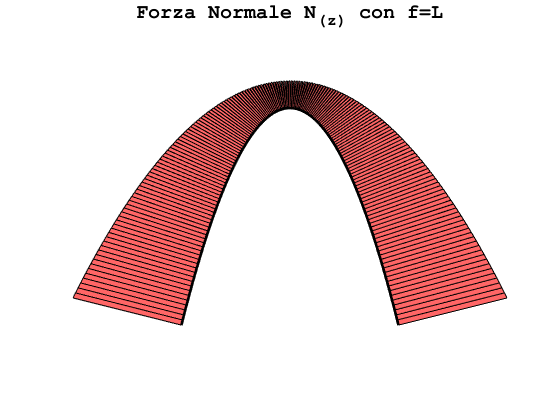

a=0:0.1:Ln;       
ang(z)=atan(diff(Y,z));
angle=ang(a);
N0n=double(Nn(a));
%% Plot f=L
figure(3)
c=1;
fig = gcf; % current figure handle
fig.Color = [1 1 1];
fig.ToolBar = 'none';
for n=1:length(a)-1 
 B=double([a(n) a(n+1)  (a(n+1)+c*N0n(n+1)*sin(angle(n+1)))  (a(n)+c*N0n(n)*sin(angle(n+1)))]);
 C=double([Y(a(n)) Y(a(n+1))  (Y(a(n+1))-c*N0n(n+1)*cos(angle(n+1)))  (Y(a(n))-c*N0n(n)*cos(angle(n)))]);
hpatch=patch(B,C,'r','Facealpha',0.6);
axis equal
axis off
hold on  
end
%Struttura
plot(a,Y(a),'-k','LineWidth',2)
title(['\fontname{Courier}\fontsize{15}Forza Normale N_(_z_) con f=L'],'color','K');
axis equal
axis off
hold on

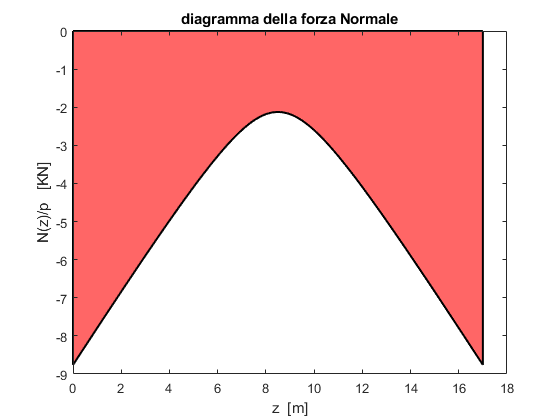

% plot per i valori
figure(4)
area(a,N0n,'FaceColor', 'r','LineWidth',1.5)
alpha(.6)
title('diagramma della forza Normale')
xlabel('z  [m]')
ylabel('N(z)/p   [KN]')
hold on


%% CASO f=L/4
fn=Ln/4;
pn=1;
Y(z)=subs(G,[f L],[fn Ln]);
Nn(z)=subs(N1E,[f L p],[fn Ln pn])

$$Nn(z) = -\frac{17\,\sqrt{\frac{{\left(2\,z-17\right)}^{2}}{289}+1}}{2}$$

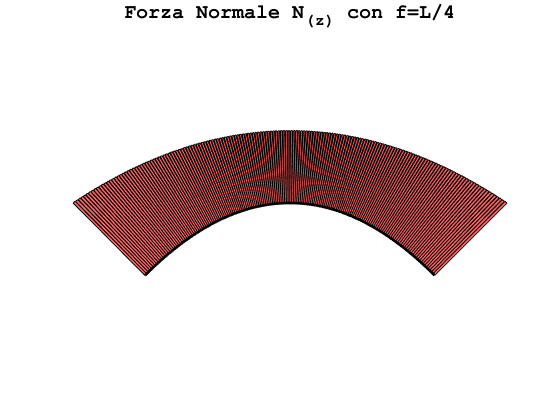

a=0:0.1:Ln;       
ang(z)=atan(diff(Y,z));
angle=ang(a);
N0n=double(Nn(a));
%% Plot f=L
figure(5)
c=0.5;
fig = gcf; % current figure handle
fig.Color = [1 1 1];
fig.ToolBar = 'none';
for n=1:length(a)-1 
 B=double([a(n) a(n+1)  (a(n+1)+c*N0n(n+1)*sin(angle(n+1)))  (a(n)+c*N0n(n)*sin(angle(n+1)))]);
 C=double([Y(a(n)) Y(a(n+1))  (Y(a(n+1))-c*N0n(n+1)*cos(angle(n+1)))  (Y(a(n))-c*N0n(n)*cos(angle(n)))]);
hpatch=patch(B,C,'r','Facealpha',0.6);
axis equal
axis off
hold on  
end
%Struttura
plot(a,Y(a),'-k','LineWidth',2)
title(['\fontname{Courier}\fontsize{15}Forza Normale N_(_z_) con f=L/4'],'color','K');
axis equal
axis off
hold on

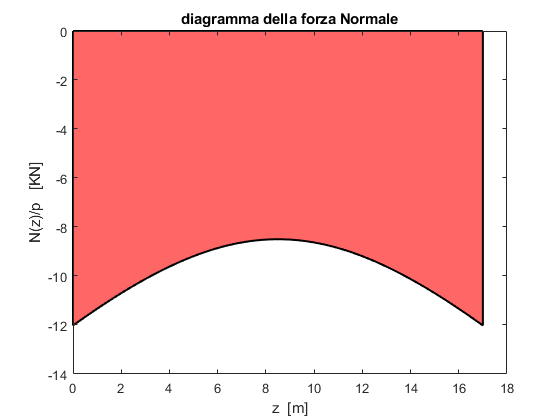

% plot per i valori
figure(6)
area(a,N0n,'FaceColor', 'r','LineWidth',1.5)
alpha(.6)
title('diagramma della forza Normale')
xlabel('z  [m]')
ylabel('N(z)/p   [KN]')
hold on